%% ================= Clustering cinématique ================= %%       
clear; clc; close all;

%% -------- Chargement de l'environnement -------- %%
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\btk'));
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Toolboxs\3D Kinematics and Inverse Dynamics'));

%% -------- Groupes de sujets -------- %%
AsymptomaticSubjects = {'A1', 'A2', 'A3', 'A4', 'A5', ...
             'A6', 'A7', 'A8', 'A9', 'A10', ...
             'A11', 'A12', 'A13', 'A14', 'A15', ...
             'A16', 'A17', 'A18', 'A19', 'A20', ...
             'A21', 'A22', 'A23', 'A24', 'A25', ...
             'A26', 'A27', 'A28', 'A29', 'A30', ...
             'A31', 'A32', 'A33', 'A34', 'A35', ...
             'A36', 'A37', 'A38', 'A39', 'A40', ...
             'A41'}

PreOPSubjects = {'S1', 'S2', 'S3', 'S4', 'S5', ...
             'S6', 'S7', 'S8', 'S9', 'S10', ...
             'S11', 'S12', 'S13'}

PostOPSubjects = {'S1', 'S2', 'S3', 'S4', 'S5', ...
             'S6', 'S7', 'S8', 'S9', 'S10', ...
             'S11', 'S12', 'S13'}

%% -------- Chemins racines -------- %%
AsymptomaticPath = 'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Asymptomatic\';
PreOPPath =        'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Pre_operation\'; 
PostOPPath =        'C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\Sujets\Post_operation\'; 

%% -------- Choix du groupe -------- %%
prompt = 'Choisissez le groupe à analyser (1 = Asymptomatiques, 2 = Pré-Opératoires, 3 = Post-Opératoires) : ';
group_choice = input(prompt);

switch group_choice
    case 1
        SelectedSubjects = AsymptomaticSubjects;
        data_path = AsymptomaticPath;
        disp('Groupe sélectionné : Asymptomatiques');
    case 2
        SelectedSubjects = PreOPSubjects;
        data_path = PreOPPath;
        disp('Groupe sélectionné : Pré-Opératoires');
    case 3
        SelectedSubjects = PostOPSubjects;
        data_path = PostOPPath;
        disp('Groupe sélectionné : Post-Opératoires');
    otherwise
        error('Choix invalide. Veuillez entrer 1, 2 ou 3.');
end

Groupe sélectionné : Pré-Opératoires


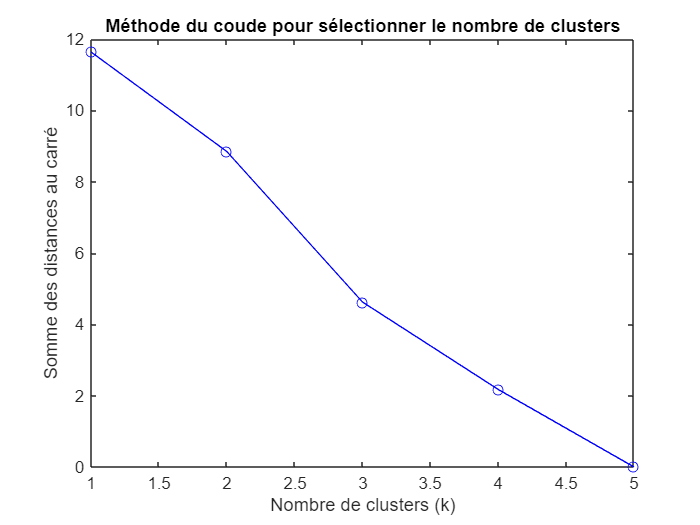

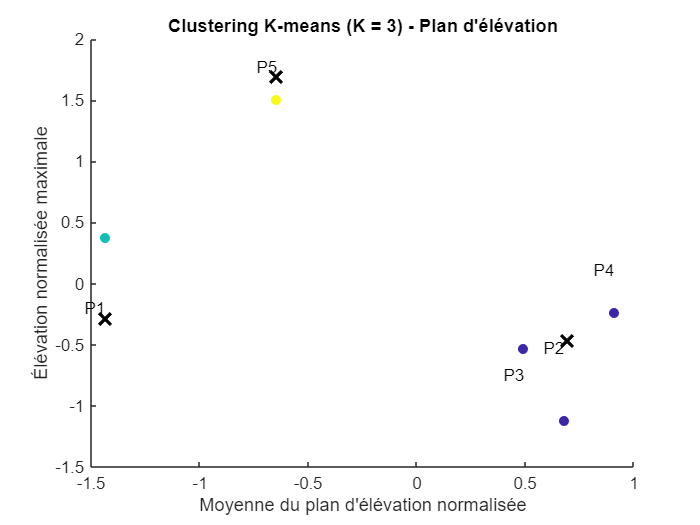

Score de silhouette moyen : 0.679
Cluster 1: P2, P3, P4
Cluster 2: P1
Cluster 3: P5



%% -------- Lancer l'analyse -------- %%
analyze_elevation_planes(SelectedSubjects, data_path);


% NB : définir le nombre de cluster selon le nombre de participants